# Sistemas Lineales invariantes en el tiempo

## Deltas de Kronecker y Dirac

1.- Intentar plotear la delta de Dirac.

2.- Plotear delta de Kronecker

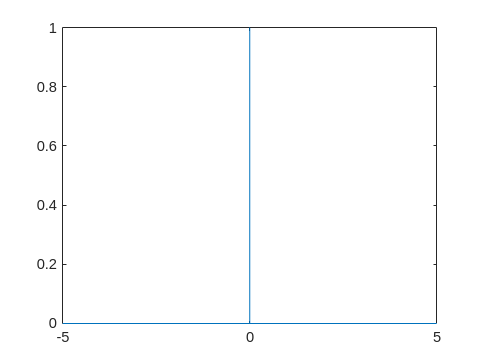

clear 

syms n t

figure
fplot(kroneckerDelta(n))

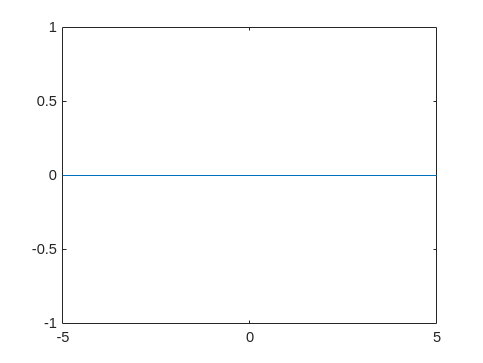


figure
fplot(dirac(t))

La delta de Dirac no se puede graficar porque en realidad no se trata de "una flecha de altura 1", sino que tiene altura infinita y Matlab no lo puede graficar.

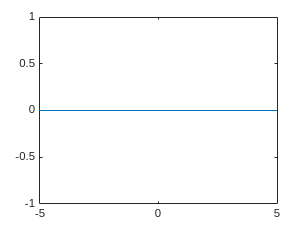

## Sifting property

1.- Crear un vector $n$ y $x$ con la señal de la imagen

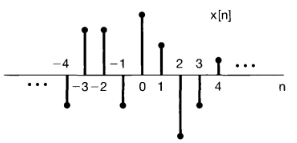

2.- Abrir elemento por elemento la siguiente suma, usando la señal anterior:

Consultar la presentación

clear 

syms n
n_d = [-4:4]

n_d =     -4    -3    -2    -1     0     1     2     3     4


x = [-1 2 2 -1 3 1 -3 -1 1]

x =     -1     2     2    -1     3     1    -3    -1     1


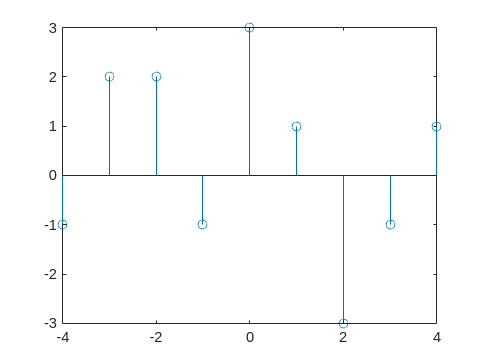


%1.-
figure
stem(n_d,x)


x_r = 0

x_r = 0


%2.-
%Porque Josué lo pidió
for i = 1:length(n_d)
    x_r = x_r + x(i)*kroneckerDelta(n-n_d(i));
end
x_r

$$x\_r = \delta_{n-1,0}-\delta_{n+1,0}-3\,\delta_{n-2,0}+2\,\delta_{n+2,0}-\delta_{n-3,0}+2\,\delta_{n+3,0}+\delta_{n-4,0}-\delta_{n+4,0}+3\,\delta_{n,0}$$


figure
stem(n_d,subs(x_r,n,n_d))

## Convolucion

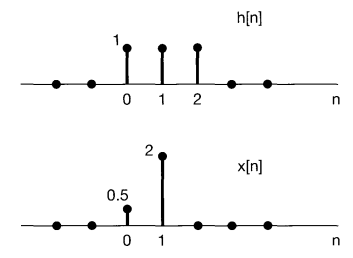

1.- Definir los vectores $n$, $h$ y $x$

2.- Escribir manualmente los vectores (Es buena idea dibujarlos) $h\left\lbrack x\left\lbrack 0\right\rbrack \right\rbrack$ y $h\left\lbrack x\left\lbrack 1\right\rbrack \right\rbrack$

3.- Escribir el resultado $y\left\lbrack n\right\rbrack =\Sigma_{k=0\;}^{k=2} h\left\lbrack x\left\lbrack n-k\right\rbrack \right\rbrack$

1.- Calcular la convolución $y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack *h\left\lbrack n\right\rbrack$ a *lápiz y papel*

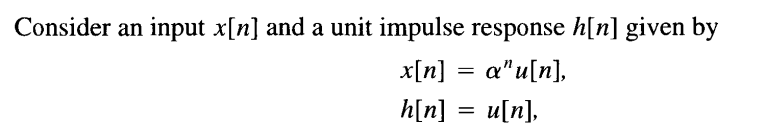

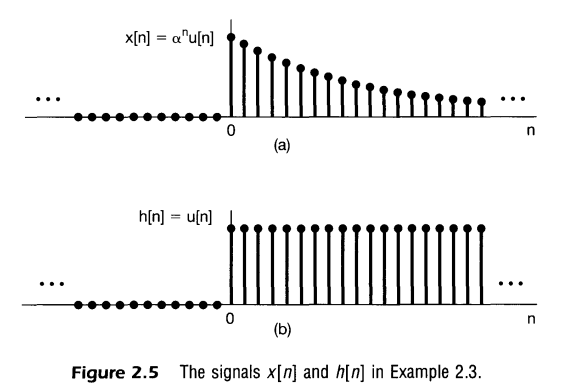

2.- Graficar el resultado

Calcular la convolución a lápiz y papel

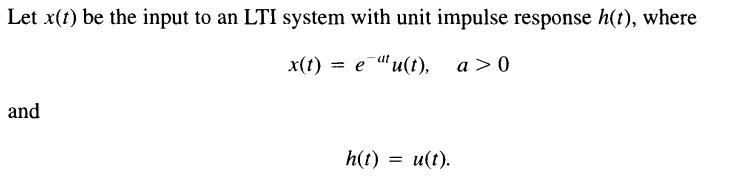

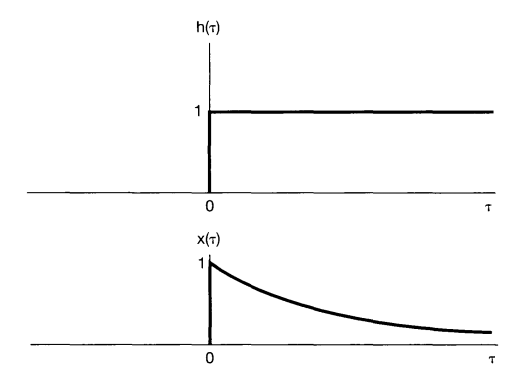--